作多线阵列图，大批量展示多条线

## 语法

## 示例

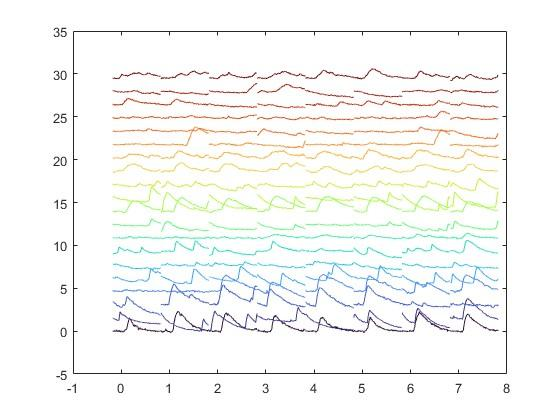

## 输入参数

Data3D(:,:,:)，作图数据，第1维时间，第2维行，第3维列

### 名称值参数

YDistance=std2(Data3D)*3，Y方向线的距离

XRange(1,2)，第1列的X范围，以后每列X范围都会自动累积。默认[1,height(Data3D)]

ColorOrder(:,3)=turbo(size(Data3D,2));，颜色顺序，将按此顺序循环画线颜色

PlotArguments(1,:)cell={}，此函数调用内置plot画线，此参数指定要传递给plot的其它参数

## 返回值

Lines(:,:)，画出的所有线条，矩阵两个维度对应Data3D中的2、3维度

**See also** [plot](matlab:doc plot)

function Lines = LineArray(Data3D,options)
arguments
	Data3D
	options.YDistance=std2(Data3D)*3
	options.XRange
	options.ColorOrder=turbo(size(Data3D,2));
	options.PlotArguments={}
end
[NumTime,NumRows,NumCols]=size(Data3D);
if isfield(options,'XRange')
	Xs=linspace(options.XRange(1),options.XRange(2),NumTime+1);
else
	Xs=1:NumTime+1;
end
Step=Xs(end)-Xs(1);
colororder(options.ColorOrder);
Lines=reshape(plot(reshape(repmat(Xs(1:end-1)+reshape(0:Step:(NumCols-1)*Step,1,1,[]),1,NumRows),NumTime,[]),reshape(Data3D+(0:options.YDistance:(NumRows-1)*options.YDistance),NumTime,[]),options.PlotArguments{:}),NumRows,NumCols);